clc; 
clear all; 
close all;
%GENERATE CARRIER SIGNAL
 Tb=1;
 fc1=2;
 fc2=5; 
t=0:(Tb/100):Tb;
c1=sqrt(2/Tb)*sin(2*pi*fc1*t);
c2=sqrt(2/Tb)*sin(2*pi*fc2*t);
%generate message signal
 N=8; 
 m=rand(1,N);
 t1=0;
 t2=Tb

t2 = 1

for i=1:N 
    t=[t1:(Tb/100):t2]
if m(i)>0.5 m(i)=1;
m_s=ones(1,length(t));
invm_s=zeros(1,length(t));
else
m(i)=0;
m_s=zeros(1,length(t));
invm_s=ones(1,length(t));
end 
message(i,:)=m_s;
%Multiplier
fsk_sig1(i,:)=c1.*m_s;
fsk_sig2(i,:)=c2.*invm_s;
 fsk=fsk_sig1+fsk_sig2;
%plotting the message signal and the modulated signaL
 subplot(3,2,2);
axis([0 N -2 2]);
 plot(t,message(i,:),'r');
title('message signal');
xlabel('t---->');
ylabel('m(t)');
grid on;
hold on; 
subplot(3,2,5);
plot(t,fsk(i,:));
title('FSK signal');
xlabel('t --- >');
ylabel('s(t)');
grid on;
hold on;
t1=t1+(Tb+.01);
t2=t2+(Tb+.01);
end 

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


t =     1.0100    1.0200    1.0300    1.0400    1.0500    1.0600    1.0700    1.0800    1.0900    1.1000    1.1100    1.1200    1.1300    1.1400    1.1500    1.1600    1.1700    1.1800    1.1900    1.2000    1.2100    1.2200    1.2300    1.2400    1.2500    1.2600    1.2700    1.2800    1.2900    1.3000    1.3100    1.3200    1.3300    1.3400    1.3500    1.3600    1.3700    1.3800    1.3900    1.4000    1.4100    1.4200    1.4300    1.4400    1.4500    1.4600    1.4700    1.4800    1.4900    1.5000


t =     2.0200    2.0300    2.0400    2.0500    2.0600    2.0700    2.0800    2.0900    2.1000    2.1100    2.1200    2.1300    2.1400    2.1500    2.1600    2.1700    2.1800    2.1900    2.2000    2.2100    2.2200    2.2300    2.2400    2.2500    2.2600    2.2700    2.2800    2.2900    2.3000    2.3100    2.3200    2.3300    2.3400    2.3500    2.3600    2.3700    2.3800    2.3900    2.4000    2.4100    2.4200    2.4300    2.4400    2.4500    2.4600    2.4700    2.4800    2.4900    2.5000    2.5100


t =     3.0300    3.0400    3.0500    3.0600    3.0700    3.0800    3.0900    3.1000    3.1100    3.1200    3.1300    3.1400    3.1500    3.1600    3.1700    3.1800    3.1900    3.2000    3.2100    3.2200    3.2300    3.2400    3.2500    3.2600    3.2700    3.2800    3.2900    3.3000    3.3100    3.3200    3.3300    3.3400    3.3500    3.3600    3.3700    3.3800    3.3900    3.4000    3.4100    3.4200    3.4300    3.4400    3.4500    3.4600    3.4700    3.4800    3.4900    3.5000    3.5100    3.5200


t =     4.0400    4.0500    4.0600    4.0700    4.0800    4.0900    4.1000    4.1100    4.1200    4.1300    4.1400    4.1500    4.1600    4.1700    4.1800    4.1900    4.2000    4.2100    4.2200    4.2300    4.2400    4.2500    4.2600    4.2700    4.2800    4.2900    4.3000    4.3100    4.3200    4.3300    4.3400    4.3500    4.3600    4.3700    4.3800    4.3900    4.4000    4.4100    4.4200    4.4300    4.4400    4.4500    4.4600    4.4700    4.4800    4.4900    4.5000    4.5100    4.5200    4.5300


t =     5.0500    5.0600    5.0700    5.0800    5.0900    5.1000    5.1100    5.1200    5.1300    5.1400    5.1500    5.1600    5.1700    5.1800    5.1900    5.2000    5.2100    5.2200    5.2300    5.2400    5.2500    5.2600    5.2700    5.2800    5.2900    5.3000    5.3100    5.3200    5.3300    5.3400    5.3500    5.3600    5.3700    5.3800    5.3900    5.4000    5.4100    5.4200    5.4300    5.4400    5.4500    5.4600    5.4700    5.4800    5.4900    5.5000    5.5100    5.5200    5.5300    5.5400


t =     6.0600    6.0700    6.0800    6.0900    6.1000    6.1100    6.1200    6.1300    6.1400    6.1500    6.1600    6.1700    6.1800    6.1900    6.2000    6.2100    6.2200    6.2300    6.2400    6.2500    6.2600    6.2700    6.2800    6.2900    6.3000    6.3100    6.3200    6.3300    6.3400    6.3500    6.3600    6.3700    6.3800    6.3900    6.4000    6.4100    6.4200    6.4300    6.4400    6.4500    6.4600    6.4700    6.4800    6.4900    6.5000    6.5100    6.5200    6.5300    6.5400    6.5500


t =     7.0700    7.0800    7.0900    7.1000    7.1100    7.1200    7.1300    7.1400    7.1500    7.1600    7.1700    7.1800    7.1900    7.2000    7.2100    7.2200    7.2300    7.2400    7.2500    7.2600    7.2700    7.2800    7.2900    7.3000    7.3100    7.3200    7.3300    7.3400    7.3500    7.3600    7.3700    7.3800    7.3900    7.4000    7.4100    7.4200    7.4300    7.4400    7.4500    7.4600    7.4700    7.4800    7.4900    7.5000    7.5100    7.5200    7.5300    7.5400    7.5500    7.5600


hold off
%Plotting binary data bits and carrier signal
subplot(3,2,1);
stem(m);
title('binary data');
xlabel('n---->');
ylabel('b(n)');
grid on;
subplot(3,2,3);
plot(t,c1);
title('carrier signal-1');
xlabel('t	>');
ylabel('c1(t)');
grid on;
subplot(3,2,4);
plot(t,c2);
title('carrier signal-2');
xlabel('t ---->');
ylabel('c2(t)');
grid on;


t1=0;
t2=Tb

t2 = 1

for i=1:N
t=[t1:(Tb/100):t2]
%correlator 
 x1=sum(c1.*fsk_sig1(i,:));
x2=sum(c2.*fsk_sig2(i,:));
x=x1-x2;
%decision device
if x>0
demod(i)= 1;
else
demod(i)=0;
end 
t1=t1+(Tb+.01);
t2=t2+(Tb+.01);
end

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


t =     1.0100    1.0200    1.0300    1.0400    1.0500    1.0600    1.0700    1.0800    1.0900    1.1000    1.1100    1.1200    1.1300    1.1400    1.1500    1.1600    1.1700    1.1800    1.1900    1.2000    1.2100    1.2200    1.2300    1.2400    1.2500    1.2600    1.2700    1.2800    1.2900    1.3000    1.3100    1.3200    1.3300    1.3400    1.3500    1.3600    1.3700    1.3800    1.3900    1.4000    1.4100    1.4200    1.4300    1.4400    1.4500    1.4600    1.4700    1.4800    1.4900    1.5000


t =     2.0200    2.0300    2.0400    2.0500    2.0600    2.0700    2.0800    2.0900    2.1000    2.1100    2.1200    2.1300    2.1400    2.1500    2.1600    2.1700    2.1800    2.1900    2.2000    2.2100    2.2200    2.2300    2.2400    2.2500    2.2600    2.2700    2.2800    2.2900    2.3000    2.3100    2.3200    2.3300    2.3400    2.3500    2.3600    2.3700    2.3800    2.3900    2.4000    2.4100    2.4200    2.4300    2.4400    2.4500    2.4600    2.4700    2.4800    2.4900    2.5000    2.5100


t =     3.0300    3.0400    3.0500    3.0600    3.0700    3.0800    3.0900    3.1000    3.1100    3.1200    3.1300    3.1400    3.1500    3.1600    3.1700    3.1800    3.1900    3.2000    3.2100    3.2200    3.2300    3.2400    3.2500    3.2600    3.2700    3.2800    3.2900    3.3000    3.3100    3.3200    3.3300    3.3400    3.3500    3.3600    3.3700    3.3800    3.3900    3.4000    3.4100    3.4200    3.4300    3.4400    3.4500    3.4600    3.4700    3.4800    3.4900    3.5000    3.5100    3.5200


t =     4.0400    4.0500    4.0600    4.0700    4.0800    4.0900    4.1000    4.1100    4.1200    4.1300    4.1400    4.1500    4.1600    4.1700    4.1800    4.1900    4.2000    4.2100    4.2200    4.2300    4.2400    4.2500    4.2600    4.2700    4.2800    4.2900    4.3000    4.3100    4.3200    4.3300    4.3400    4.3500    4.3600    4.3700    4.3800    4.3900    4.4000    4.4100    4.4200    4.4300    4.4400    4.4500    4.4600    4.4700    4.4800    4.4900    4.5000    4.5100    4.5200    4.5300


t =     5.0500    5.0600    5.0700    5.0800    5.0900    5.1000    5.1100    5.1200    5.1300    5.1400    5.1500    5.1600    5.1700    5.1800    5.1900    5.2000    5.2100    5.2200    5.2300    5.2400    5.2500    5.2600    5.2700    5.2800    5.2900    5.3000    5.3100    5.3200    5.3300    5.3400    5.3500    5.3600    5.3700    5.3800    5.3900    5.4000    5.4100    5.4200    5.4300    5.4400    5.4500    5.4600    5.4700    5.4800    5.4900    5.5000    5.5100    5.5200    5.5300    5.5400


t =     6.0600    6.0700    6.0800    6.0900    6.1000    6.1100    6.1200    6.1300    6.1400    6.1500    6.1600    6.1700    6.1800    6.1900    6.2000    6.2100    6.2200    6.2300    6.2400    6.2500    6.2600    6.2700    6.2800    6.2900    6.3000    6.3100    6.3200    6.3300    6.3400    6.3500    6.3600    6.3700    6.3800    6.3900    6.4000    6.4100    6.4200    6.4300    6.4400    6.4500    6.4600    6.4700    6.4800    6.4900    6.5000    6.5100    6.5200    6.5300    6.5400    6.5500


t =     7.0700    7.0800    7.0900    7.1000    7.1100    7.1200    7.1300    7.1400    7.1500    7.1600    7.1700    7.1800    7.1900    7.2000    7.2100    7.2200    7.2300    7.2400    7.2500    7.2600    7.2700    7.2800    7.2900    7.3000    7.3100    7.3200    7.3300    7.3400    7.3500    7.3600    7.3700    7.3800    7.3900    7.4000    7.4100    7.4200    7.4300    7.4400    7.4500    7.4600    7.4700    7.4800    7.4900    7.5000    7.5100    7.5200    7.5300    7.5400    7.5500    7.5600


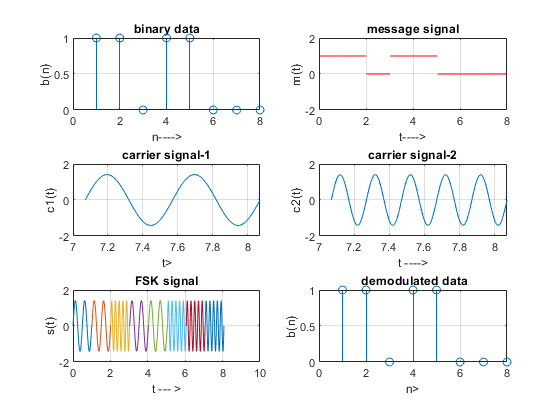

%Plotting the demodulated data bits
subplot(3,2,6);
stem(demod);
title(' demodulated data');
xlabel('n	>');
ylabel('b(n)');
grid on;